clear;
clc;
DEFINE;

`%%% PARAMETERS %%%`

duration =10; % in [sec]
Fs_nominal = 10000; %in [Hz]         % nominal sampling frequency (Hz)
N          = duration * Fs_nominal;
dt         = duration / (N - 1);     % time step between samples
sin_wave(:, AMP  ) = [0.75  ];
sin_wave(:, FREQ ) = [79    ];
sin_wave(:, PHASE) = [pi / 3];
max_freq = max(sin_wave(:, 2));
min_freq = min(sin_wave(:, 2));

Fs_nyquist = Fs_nominal / 2;
noise_RMS = 2.2;
win_samples = WIN_SIZE(WIN_SIZE > floor(Fs_nominal / min_freq)...
    & WIN_SIZE < N/2);

`%%%% SIGNAL GENERATION %%%`

[signal, sin_signal, norm_nois, t, ref_moments] =...
    generate_signal(N, sin_wave, noise_RMS, duration);
if max_freq >= Fs_nyquist
    error('generate_signal_data:nyquist', ...
        ['Maximum sine frequency (%g Hz) must be less than Fs/2 = %g Hz.\n' ...
        'Increase num_samples or reduce the highest frequency component.'], ...
        max_freq, Fs_nyquist);
end

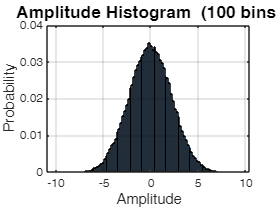

fig_hist = figure('Name', 'Signal Histogram', 'NumberTitle', 'off', ...
    'Units', 'normalized');
histogram(signal, HIST_BINS, 'Normalization', 'probability', ...
    'FaceColor', [0.2, 0.5, 0.8]);
ylabel('Probability', 'FontSize', 11);
xlabel('Amplitude', 'FontSize', 11);
title(sprintf('Amplitude Histogram  (%d bins)', HIST_BINS), ...
    'FontSize', 13, 'FontWeight', 'bold');
grid on;

fig_psd = figure('Name', 'FFT Periodogram PSD', 'NumberTitle', 'off', ...
    'Units', 'normalized');
plot(f_psd, 10*log10(psd_vec), 'b-', 'LineWidth', 0.8);
xlabel('Frequency (Hz)',    'FontSize', 11);
ylabel('PSD (dB/Hz)',       'FontSize', 11);
title('Power Spectral Density – FFT Periodogram', ...
    'FontSize', 13, 'FontWeight', 'bold');
xlim([0, Fs_nyquist]);
grid on;

fig_welch = figure('Name', 'Welch PSD', 'NumberTitle', 'off', ...
    'Units', 'normalized');
plot(f_welch, 10*log10(psd_welch), 'r-', 'LineWidth', 0.8);
xlabel('Frequency (Hz)',    'FontSize', 11);
ylabel('PSD (dB/Hz)',       'FontSize', 11);
title(sprintf('Welch PSD  [%s]', welch_method), ...
    'FontSize', 12, 'FontWeight', 'bold');
xlim([0, Fs_nyquist]);
grid on;

fig_fft = figure('Name', 'FFT Magnitude Spectrum', 'NumberTitle', 'off', ...
    'Units', 'normalized');
stem(f_fft, X_onesided, 'b.', 'MarkerSize', 3);
xlabel('Frequency (Hz)',  'FontSize', 11);
ylabel('|X(f)| / N  (normalised amplitude)', 'FontSize', 10);
title('FFT Magnitude Spectrum (one-sided, normalised)', ...
    'FontSize', 12, 'FontWeight', 'bold');
xlim([0, Fs_nyquist]);
grid on;